%calculating the mean first passage time using Gillespie simulations
%to investigate effect of branch migration domain length on RNA/DNA TMSD
%kinetics

%b = 20 %define branch migration domain length
g = 2 %define invader toehold length 

g = 2


R = 1.987/1000 % universal gas constant in kcal/K/mol

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp 

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGrd = -1*R*temp

dGrd = -0.5924

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

N = 10 %number of simulations

N = 10

avr_first_pass_time = zeros(1,30)

avr_first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ind_first_pass_time = zeros(30, N)

ind_first_pass_time =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


k_eff = zeros(1, 30)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ind_k_eff = zeros(30, N)

ind_k_eff =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


std_err_fpt = zeros(1, 30)

std_err_fpt =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


std_err_k_eff = zeros(1, 30)

std_err_k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


std_err_log_k = zeros(1,30)

std_err_log_k =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through branch migration domain lengths
for b = 10:40
    
    %define forward and reverse rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp((dGbp + dGrd)/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp((dGbp + dGrd)/(R*temp))
    k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_Cf = k_bp * exp(-dGbm/(R*temp))
    k_Cr = k_bp * exp(-(dGbm - dGrd)/(R*temp))
    k_CD = k_bp * exp(-dGbm/(R*temp));
    k_DC = 0 
    k_DD = 1
    
    first_pass_time = zeros(1,N)
    
    %create arrays of forward and reverse rates
    if g == 1
        Kf = [k_AB1, k_C1f, repmat(k_Cf, [1, b-2]), k_CD, k_DD]
        Kb = [k_AA, k_B1A, k_Cr, repmat(k_Cr, [1 b-2]), k_DC]
    else
        Kf = [k_AB1, k_BC1ij, repmat(k_BC1ij, [1, g-2]), k_C1f, repmat(k_Cf, [1, b-2]), k_CD, k_DD]
        Kb = [k_AA, k_B1A, repmat(k_BC1ji, [1, g-2]), k_BC1ji, k_Cr, repmat(k_Cr, [1, b-2]), k_DC]
    end
    
    totalrate = Kf + Kb; %define total rate
    Pf = Kf./totalrate; %define probability of forward transition
    Pb = 1-Pf; %define probability of reverse transition
    %loop through simulations
    for n = 1:N 
        state = 1; %define initial state
        t = 0; %define initial time
        %restrict to states which can be reached
        while (state >=1 && state < (2 + g + b)) 
            t = t - (1/totalrate(state))*log(rand()); %calculate time for transition
            %calculate whether forward or reverse transition
            if rand() <= Pf(state) 
                state = state +1; %update state forward
            else
                state = state -1; %update state backward
            end
        end
        first_pass_time(n) =  t; 
        ind_first_pass_time(b-9,n) = first_pass_time(n);
        ind_k_eff(b-9,n) = 1/(first_pass_time(n)*(5*10^-8));
    end
    std_err_fpt(b-9) = std(ind_first_pass_time(b-9, :))/sqrt(N); %calculate the standard error
    std_err_k_eff(b-9) = std(ind_k_eff(b-9, :))/sqrt(N);
    std_err_log_k(b-9) = std(log10(ind_k_eff(b-9,:))/sqrt(N)); 
    avr_first_pass_time(b-9) = mean(first_pass_time) %calculate first passage time
    k_eff(b-9) = 1/(mean(first_pass_time)*(5*10^-8)) %calculate effective rate constant
end

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time =   398.2281         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+04 *

    5.0222         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time =   398.2281  176.5693         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+05 *

    0.5022    1.1327         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time =   398.2281  176.5693  358.9989         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+05 *

    0.5022    1.1327    0.5571         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+05 *

    0.5022    1.1327    0.5571    0.4487         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+05 *

    0.5022    1.1327    0.5571    0.4487    0.4384         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+05 *

    0.5022    1.1327    0.5571    0.4487    0.4384    0.2266         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409  500.0773         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+05 *

    0.5022    1.1327    0.5571    0.4487    0.4384    0.2266    0.3999         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409  500.0773  370.3879         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+05 *

    0.5022    1.1327    0.5571    0.4487    0.4384    0.2266    0.3999    0.5400         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb = 	1.0e+06 *

         0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409  500.0773  370.3879  829.2633         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.5022    1.1327    0.5571    0.4487    0.4384    0.2266    0.3999    0.5400    0.2412         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409  500.0773  370.3879  829.2633  255.0353         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.5022    1.1327    0.5571    0.4487    0.4384    0.2266    0.3999    0.5400    0.2412    0.7842         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409  500.0773  370.3879  829.2633  255.0353  347.6545         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.5022    1.1327    0.5571    0.4487    0.4384    0.2266    0.3999    0.5400    0.2412    0.7842    0.5753         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409  500.0773  370.3879  829.2633  255.0353  347.6545  291.0814         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.5022    1.1327    0.5571    0.4487    0.4384    0.2266    0.3999    0.5400    0.2412    0.7842    0.5753    0.6871         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409  500.0773  370.3879  829.2633  255.0353  347.6545  291.0814  321.4631         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.5022    1.1327    0.5571    0.4487    0.4384    0.2266    0.3999    0.5400    0.2412    0.7842    0.5753    0.6871    0.6222         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409  500.0773  370.3879  829.2633  255.0353  347.6545  291.0814  321.4631  207.7430         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.5022    1.1327    0.5571    0.4487    0.4384    0.2266    0.3999    0.5400    0.2412    0.7842    0.5753    0.6871    0.6222    0.9627         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409  500.0773  370.3879  829.2633  255.0353  347.6545  291.0814  321.4631  207.7430  468.7388         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.5022    1.1327    0.5571    0.4487    0.4384    0.2266    0.3999    0.5400    0.2412    0.7842    0.5753    0.6871    0.6222    0.9627    0.4267         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409  500.0773  370.3879  829.2633  255.0353  347.6545  291.0814  321.4631  207.7430  468.7388  391.8376         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.5022    1.1327    0.5571    0.4487    0.4384    0.2266    0.3999    0.5400    0.2412    0.7842    0.5753    0.6871    0.6222    0.9627    0.4267    0.5104         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409  500.0773  370.3879  829.2633  255.0353  347.6545  291.0814  321.4631  207.7430  468.7388  391.8376  443.8139         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.5022    1.1327    0.5571    0.4487    0.4384    0.2266    0.3999    0.5400    0.2412    0.7842    0.5753    0.6871    0.6222    0.9627    0.4267    0.5104    0.4506         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000    0.0000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121         0


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409  500.0773  370.3879  829.2633  255.0353  347.6545  291.0814  321.4631  207.7430  468.7388  391.8376  443.8139  519.1651         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.5022    1.1327    0.5571    0.4487    0.4384    0.2266    0.3999    0.5400    0.2412    0.7842    0.5753    0.6871    0.6222    0.9627    0.4267    0.5104    0.4506    0.3852         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    5.4000


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409  500.0773  370.3879  829.2633  255.0353  347.6545  291.0814  321.4631  207.7430  468.7388  391.8376  443.8139  519.1651  350.7857         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.5022    1.1327    0.5571    0.4487    0.4384    0.2266    0.3999    0.5400    0.2412    0.7842    0.5753    0.6871    0.6222    0.9627    0.4267    0.5104    0.4506    0.3852    0.5701         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409  500.0773  370.3879  829.2633  255.0353  347.6545  291.0814  321.4631  207.7430  468.7388  391.8376  443.8139  519.1651  350.7857  385.6048         0         0         0         0         0         0         0         0         0         0


k_eff =     0.5022    1.1327    0.5571    0.4487    0.4384    0.2266    0.3999    0.5400    0.2412    0.7842    0.5753    0.6871    0.6222    0.9627    0.4267    0.5104    0.4506    0.3852    0.5701    0.5187         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409  500.0773  370.3879  829.2633  255.0353  347.6545  291.0814  321.4631  207.7430  468.7388  391.8376  443.8139  519.1651  350.7857  385.6048  315.5856         0         0         0         0         0         0         0         0         0


k_eff =     0.5022    1.1327    0.5571    0.4487    0.4384    0.2266    0.3999    0.5400    0.2412    0.7842    0.5753    0.6871    0.6222    0.9627    0.4267    0.5104    0.4506    0.3852    0.5701    0.5187    0.6337         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409  500.0773  370.3879  829.2633  255.0353  347.6545  291.0814  321.4631  207.7430  468.7388  391.8376  443.8139  519.1651  350.7857  385.6048  315.5856  298.4307         0         0         0         0         0         0         0         0


k_eff =     0.5022    1.1327    0.5571    0.4487    0.4384    0.2266    0.3999    0.5400    0.2412    0.7842    0.5753    0.6871    0.6222    0.9627    0.4267    0.5104    0.4506    0.3852    0.5701    0.5187    0.6337    0.6702         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409  500.0773  370.3879  829.2633  255.0353  347.6545  291.0814  321.4631  207.7430  468.7388  391.8376  443.8139  519.1651  350.7857  385.6048  315.5856  298.4307  464.1750         0         0         0         0         0         0         0


k_eff =     0.5022    1.1327    0.5571    0.4487    0.4384    0.2266    0.3999    0.5400    0.2412    0.7842    0.5753    0.6871    0.6222    0.9627    0.4267    0.5104    0.4506    0.3852    0.5701    0.5187    0.6337    0.6702    0.4309         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409  500.0773  370.3879  829.2633  255.0353  347.6545  291.0814  321.4631  207.7430  468.7388  391.8376  443.8139  519.1651  350.7857  385.6048  315.5856  298.4307  464.1750  405.9911         0         0         0         0         0         0


k_eff =     0.5022    1.1327    0.5571    0.4487    0.4384    0.2266    0.3999    0.5400    0.2412    0.7842    0.5753    0.6871    0.6222    0.9627    0.4267    0.5104    0.4506    0.3852    0.5701    0.5187    0.6337    0.6702    0.4309    0.4926         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409  500.0773  370.3879  829.2633  255.0353  347.6545  291.0814  321.4631  207.7430  468.7388  391.8376  443.8139  519.1651  350.7857  385.6048  315.5856  298.4307  464.1750  405.9911  305.1957         0         0         0         0         0


k_eff =     0.5022    1.1327    0.5571    0.4487    0.4384    0.2266    0.3999    0.5400    0.2412    0.7842    0.5753    0.6871    0.6222    0.9627    0.4267    0.5104    0.4506    0.3852    0.5701    0.5187    0.6337    0.6702    0.4309    0.4926    0.6553         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409  500.0773  370.3879  829.2633  255.0353  347.6545  291.0814  321.4631  207.7430  468.7388  391.8376  443.8139  519.1651  350.7857  385.6048  315.5856  298.4307  464.1750  405.9911  305.1957  477.6497         0         0         0         0


k_eff =     0.5022    1.1327    0.5571    0.4487    0.4384    0.2266    0.3999    0.5400    0.2412    0.7842    0.5753    0.6871    0.6222    0.9627    0.4267    0.5104    0.4506    0.3852    0.5701    0.5187    0.6337    0.6702    0.4309    0.4926    0.6553    0.4187         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409  500.0773  370.3879  829.2633  255.0353  347.6545  291.0814  321.4631  207.7430  468.7388  391.8376  443.8139  519.1651  350.7857  385.6048  315.5856  298.4307  464.1750  405.9911  305.1957  477.6497  471.2380         0         0         0


k_eff =     0.5022    1.1327    0.5571    0.4487    0.4384    0.2266    0.3999    0.5400    0.2412    0.7842    0.5753    0.6871    0.6222    0.9627    0.4267    0.5104    0.4506    0.3852    0.5701    0.5187    0.6337    0.6702    0.4309    0.4926    0.6553    0.4187    0.4244         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409  500.0773  370.3879  829.2633  255.0353  347.6545  291.0814  321.4631  207.7430  468.7388  391.8376  443.8139  519.1651  350.7857  385.6048  315.5856  298.4307  464.1750  405.9911  305.1957  477.6497  471.2380  374.7388         0         0


k_eff =     0.5022    1.1327    0.5571    0.4487    0.4384    0.2266    0.3999    0.5400    0.2412    0.7842    0.5753    0.6871    0.6222    0.9627    0.4267    0.5104    0.4506    0.3852    0.5701    0.5187    0.6337    0.6702    0.4309    0.4926    0.6553    0.4187    0.4244    0.5337         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409  500.0773  370.3879  829.2633  255.0353  347.6545  291.0814  321.4631  207.7430  468.7388  391.8376  443.8139  519.1651  350.7857  385.6048  315.5856  298.4307  464.1750  405.9911  305.1957  477.6497  471.2380  374.7388  320.5504         0


k_eff =     0.5022    1.1327    0.5571    0.4487    0.4384    0.2266    0.3999    0.5400    0.2412    0.7842    0.5753    0.6871    0.6222    0.9627    0.4267    0.5104    0.4506    0.3852    0.5701    0.5187    0.6337    0.6702    0.4309    0.4926    0.6553    0.4187    0.4244    0.5337    0.6239         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409  500.0773  370.3879  829.2633  255.0353  347.6545  291.0814  321.4631  207.7430  468.7388  391.8376  443.8139  519.1651  350.7857  385.6048  315.5856  298.4307  464.1750  405.9911  305.1957  477.6497  471.2380  374.7388  320.5504  563.1338


k_eff =     0.5022    1.1327    0.5571    0.4487    0.4384    0.2266    0.3999    0.5400    0.2412    0.7842    0.5753    0.6871    0.6222    0.9627    0.4267    0.5104    0.4506    0.3852    0.5701    0.5187    0.6337    0.6702    0.4309    0.4926    0.6553    0.4187    0.4244    0.5337    0.6239    0.3552


k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


avr_first_pass_time =   398.2281  176.5693  358.9989  445.7558  456.2376  882.6409  500.0773  370.3879  829.2633  255.0353  347.6545  291.0814  321.4631  207.7430  468.7388  391.8376  443.8139  519.1651  350.7857  385.6048  315.5856  298.4307  464.1750  405.9911  305.1957  477.6497  471.2380  374.7388  320.5504  563.1338


k_eff =     0.5022    1.1327    0.5571    0.4487    0.4384    0.2266    0.3999    0.5400    0.2412    0.7842    0.5753    0.6871    0.6222    0.9627    0.4267    0.5104    0.4506    0.3852    0.5701    0.5187    0.6337    0.6702    0.4309    0.4926    0.6553    0.4187    0.4244    0.5337    0.6239    0.3552


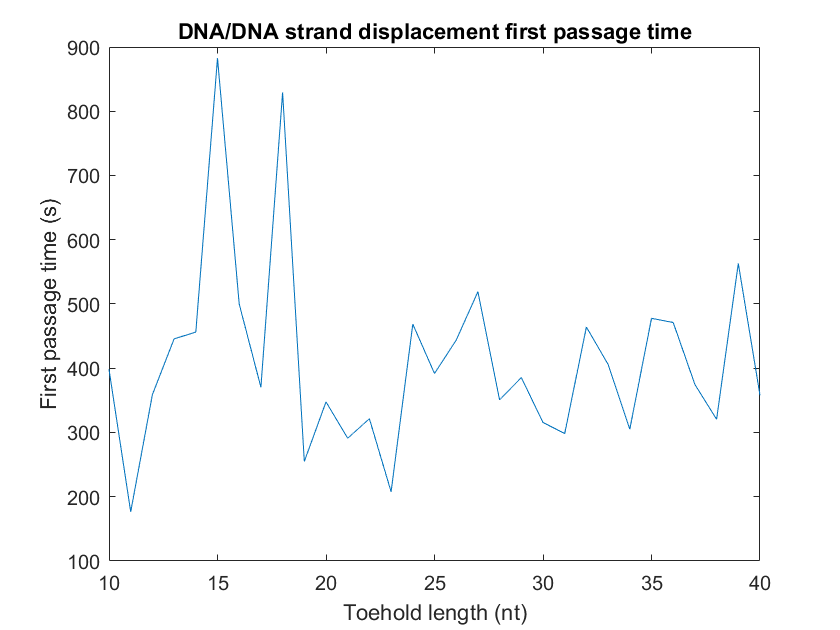

plot(10:40, avr_first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

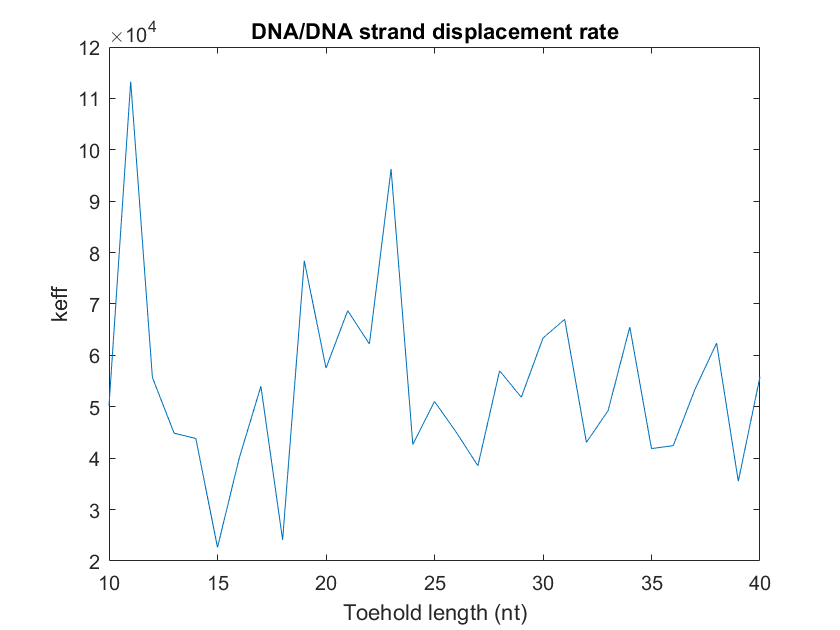


plot(10:40, k_eff)
ylabel('keff')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement rate')

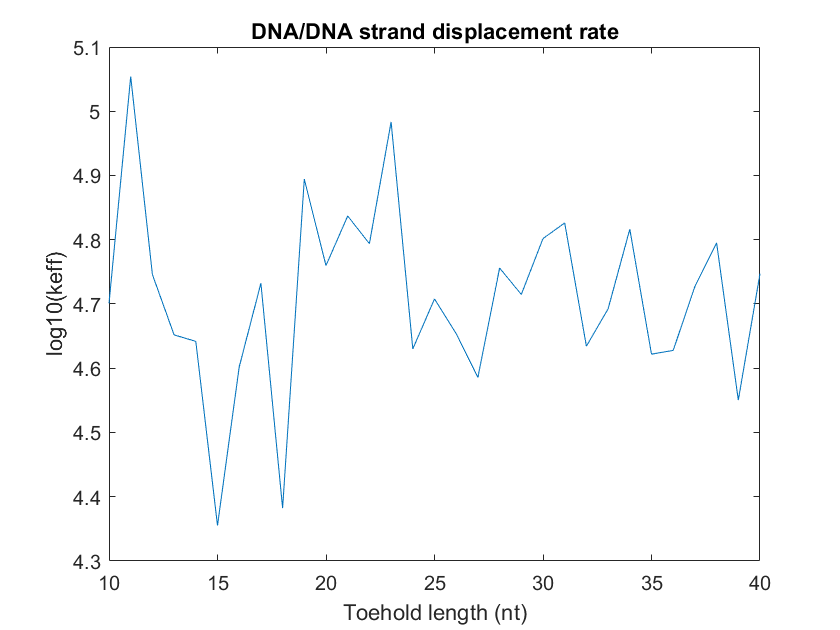


plot(10:40, log10(k_eff))
ylabel('log10(keff)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement rate')

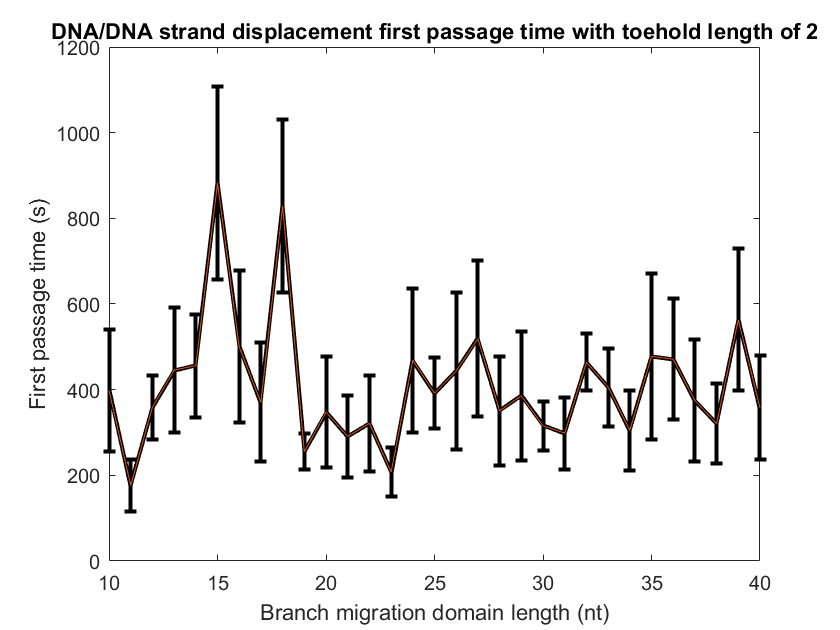


errorbar(10:40, avr_first_pass_time, std_err_fpt , 'k', 'linewidth', 2)
hold on
plot(10:40, avr_first_pass_time, 'linewidth', 0.5)
xlabel('Branch migration domain length (nt)')
ylabel('First passage time (s)')
title('DNA/DNA strand displacement first passage time with toehold length of ' + string(g))

hold off

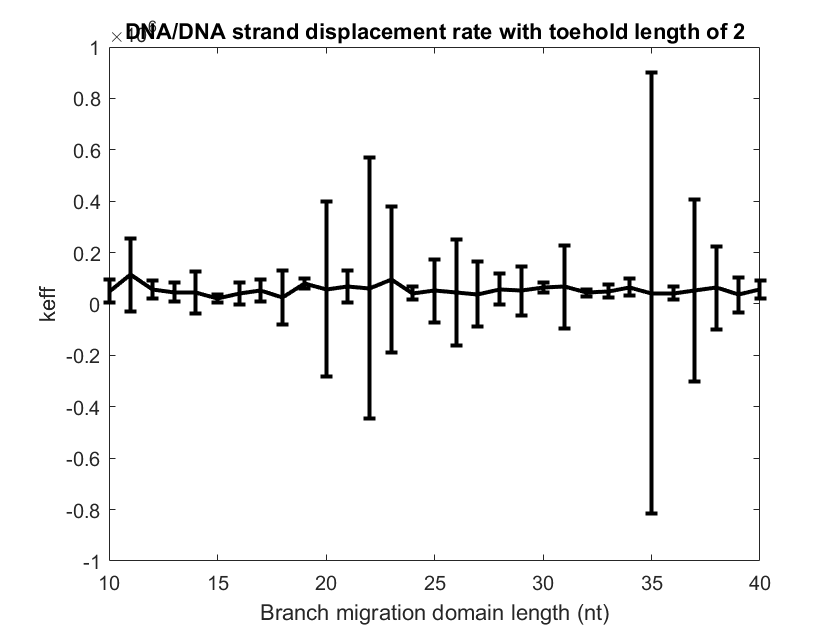


errorbar(10:40, k_eff, std_err_k_eff, 'k', 'linewidth', 2)
xlabel('Branch migration domain length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate with toehold length of ' + string(g))
hold off

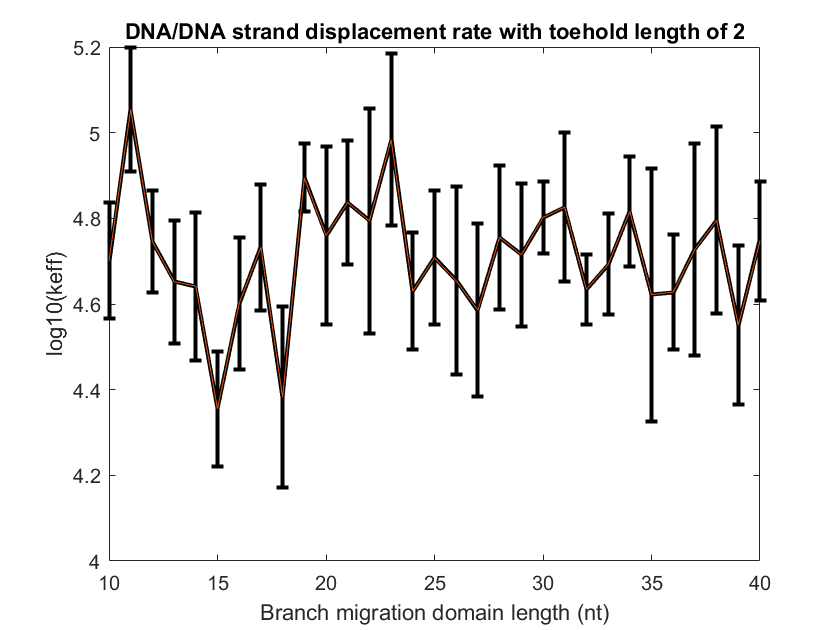


errorbar(10:40, log10(k_eff), std_err_log_k, 'k', 'linewidth', 2)
hold on
plot(10:40, log10(k_eff), '', 'linewidth', 0.5)
xlabel('Branch migration domain length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate with toehold length of ' + string(g))
hold off